# Cardiac 201 Test

% Load the data in position 1
parpool("local", 8)
input_path = 'E:\Cardiac_201\'; 
        

block_size = [256 256 70 4 5];

tic

useGPU = true;
curr_gpu = gpuDevice();

cardiac_test = new_STARMapDataset(input_path, 'useGPU', useGPU);
cardiac_test = cardiac_test.LoadRawImages('data_dir', 'position1');
cardiac_test.rawImages = gpuArray(cardiac_test.rawImages(1:512, :, :, :, :));
cardiac_test = cardiac_test.SwapChannels;
cardiac_test = cardiac_test.MinMaxNormalize;
cardiac_test = cardiac_test.MorphoRecon;
cardiac_test = cardiac_test.GlobalRegistration;
cardiac_test.rawImages = [];
cardiac_test.registeredImages = gather(cardiac_test.registeredImages);
reset(curr_gpu)

tic
block_idx = BlockTest(cardiac_test.registeredImages, block_size, 0);
block_idx = ValidIdx(block_idx, 256);
Nblock = numel(block_idx)

serial_goodSpots = [];
serial_goodReads = [];
 
ticBytes(gcp);
parfor n=1:Nblock
    idx = block_idx{n};
    
    curr_gpu = gpuDevice();
    
    curr_run = new_STARMapDataset(input_path, block_size, 'useGPU', useGPU);
    curr_run.registeredImages = gpuArray(cardiac_test.registeredImages(...
        idx(1,1):idx(1,2),...
        idx(2,1):idx(2,2),...
        :,:,:));

    curr_run = curr_run.LocalRegistration('Iterations', 10);
    %reset(curr_gpu);
    %curr_run.gpuImages = gpuArray(curr_run.registeredImages);
    curr_run = curr_run.SpotFinding('Method', "max3d", 'qualityThreshold', 0.01, 'volumeThreshold', 0, 'showPlots', false);
    if numel(curr_run.allSpots) ~= 0
        curr_run = curr_run.ReadsExtraction('showPlots',false); 
        curr_run = curr_run.LoadCodebook;
        curr_run = curr_run.ReadsFiltration('showPlots',false);
        
        offsets = [idx(2,1) - 1 idx(1,1) - 1 0]
        offsets = repmat(offsets, size(curr_run.goodSpots, 1), 1);
        curr_run.goodSpots = curr_run.goodSpots + int16(offsets);
        
        serial_goodSpots = [serial_goodSpots; curr_run.goodSpots];
        serial_goodReads = [serial_goodReads; curr_run.goodReads];
        %all_score = [all_score; curr_run.FilterScores];
        %all_counts = all_counts + size(curr_run.allSpots, 1);
    end
    reset(curr_gpu);
end
tocBytes(gcp)

reset(gpuDevice)
toc

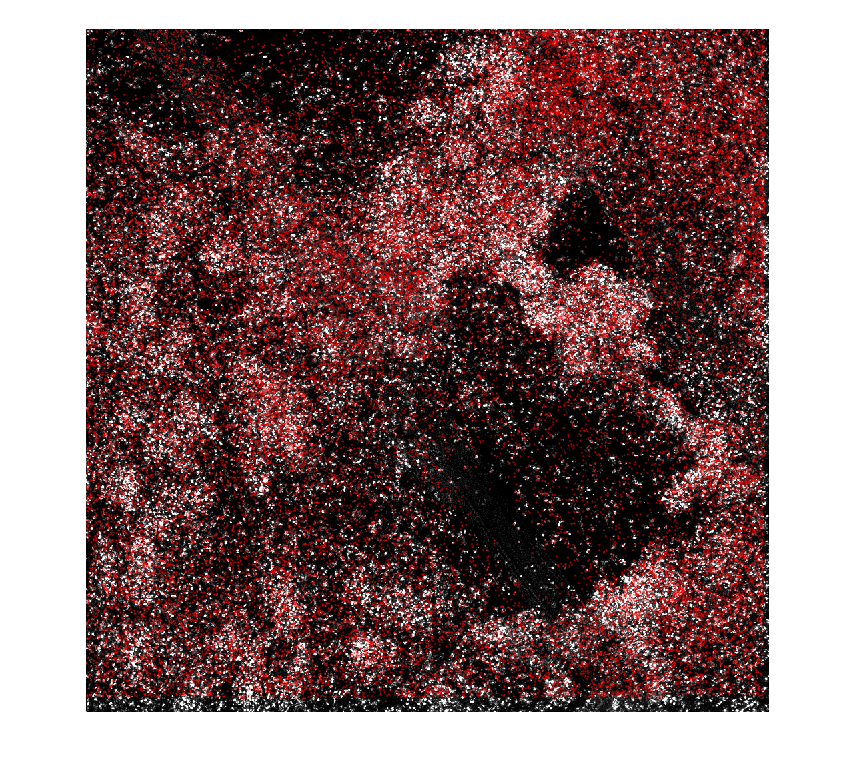

figure
img_max = max(cardiac_run.registeredImages(:,:,:,1,1), [], 3);
imshow(img_max)
hold on
plot(all_goodSpots(:,1), all_goodSpots(:,2), '.', "Color", 'red', "MarkerSize", 2)
hold off

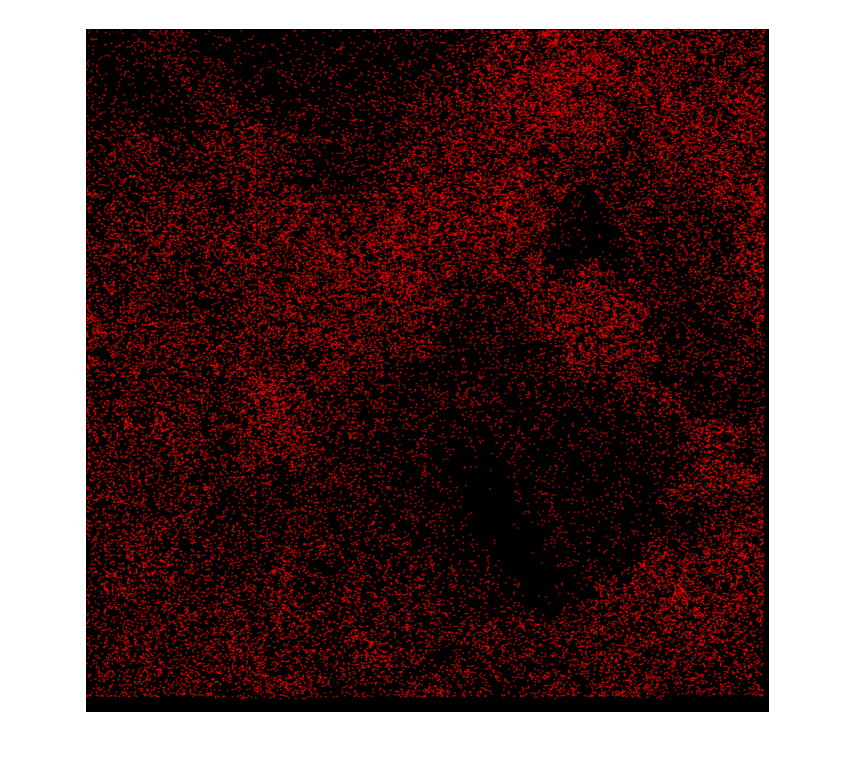

seg_path = fullfile('E:/Cardiac_201/output/reads_assignment/position1/seg_img.tif');
seg_img = imread(seg_path);

figure
imshow(seg_img)
hold on
plot(all_goodSpots(:,1), all_goodSpots(:,2), '.', "Color", 'red', "MarkerSize", 2)
hold off